% This script demonstrates the Reachset Optimal Control Algorithm on the 
% turn right maneuver of a car

% load benchmark parameter
Param = param_car();

% define algorithm options
Opts = [];

Opts.N = 10;                  % number of time steps
Opts.reachSteps = 5;          % number of reachability steps (optimization)
Opts.reachStepsFin = 25;      % num. of reach. steps (final reachable set)
Opts.maxIter = 3;             % max. number of iterations for optimization
Opts.finStateCon = false;     % final reach. set in shifted init. set
Opts.scale = [0.3;0.7];       % scaling factor for tightend input set
Opts.Q = diag([0.5 1 1 1]);   % state weighting matrix
Opts.R = 0.02*eye(2);         % input weighting matrix
Opts.Qff = diag([1,10,1,1]);  % state weighting matrix (feedforward contr.)
Opts.Rff = 0.01*eye(2);       % input weighting matrix (feedforward contr.)
Opts.refTraj.Q = eye(4);      % state weighting matrix (reference traj.)
Opts.refTraj.R = Opts.Rff;    % input weighting matrix (reference traj.)

% offline phase computations
clock = tic;
[objContr,res] = combinedControl('car',Param,Opts);
tComp = toc(clock);

disp(['Computation time: ',num2str(tComp),' s']);

Computation time: 176.8301 s


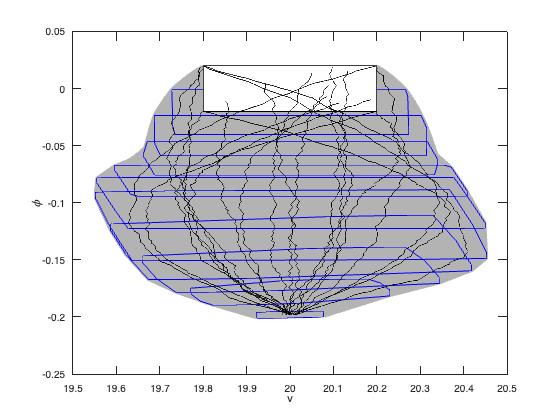


% simulation 
[resSim,~,~] = simulateRandom(objContr);

% visualization
figure; hold on; box on
plotReach(res,[1,2],[.7 .7 .7]);
plotReachTimePoint(res,[1,2],'b');
plot(Param.R0,[1,2],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[1,2],'k');
xlabel('v'); ylabel('\phi');

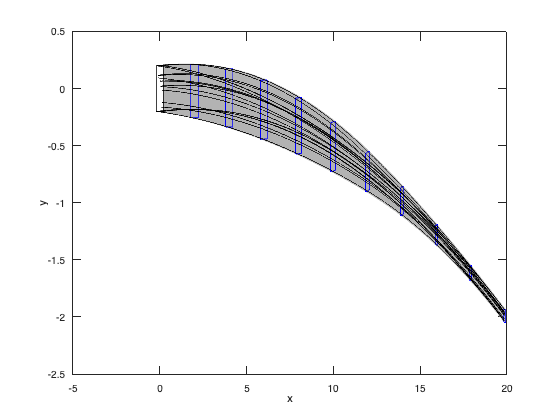


figure; hold on; box on
plotReach(res,[3,4],[.7 .7 .7]);
plotReachTimePoint(res,[3,4],'b');
plot(Param.R0,[3,4],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[3,4],'k');
xlabel('x'); ylabel('y');